# Testbed for Trust-based Mobile Crowd Sensing System

## Testbed:

Initially, the testbed contains 1000 users that consist of 250 high quality users, 500 low quality users and 250 malicious users.

Let shuffle  all types of the users in a 1000-element array (shuffledArray)

The number of high quality users, low quality users and malicious users will be changed in order for the comparison between trust-based MCS system and a QoI-based MCS system.

## Scenarios:

- A mobile device user could be either a sensing service provider for one task and a sensing service requester for another task.

- We run 1000 sensing tasks, each task requires a number of sensing service providers from 2 to 500. Each task is associated with a specific user as the sensing service requester.

- Will calculate the average of the QoD after 1000 tasks for comparison between trust-based MCS and QoD-based MCS


hqusers_num = 50;
lqusers_num = 50;
mausers_num = 25;
users_num = 200;

tasks_num = 1000;

provider_min = 2;
provider_max = round(users_num/2);

## Starting to build...

## Setup the users

- The high quality users behave according to the model proposed in user models files so that their QoDs follow a beta distribution: 

- Alpha is randomly set in the range [10-15]

- Beta is randomly set in the range [3.0-5.0]

x = linspace(0, 1, 1000);
hold on;
hqusers_mat = zeros(hqusers_num, tasks_num);
for i=1:hqusers_num
    ah = rand()*5 + 10; % random number in the range [10-15]
    bh = rand()*2 + 3; % random number in the range [3.0-5.0]
    hqusers_pd = makedist('Beta', 'a', ah, 'b', bh);
    hqusers_mat(i,:) = random(hqusers_pd, 1, tasks_num);
    plot(x, pdf(hqusers_pd, x), 'Color', [i/hqusers_num, 0, 1]);
end

     2. The low quality users behave according to the model proposed in user models files so that their QoDs follow a beta distribution: 

- Alpha is randomly set in the range [9-12]

- Beta is randomly set in the range [7-9]

lqusers_mat = zeros(lqusers_num, tasks_num);
for i=1:lqusers_num
    al = rand()*3 + 9; % random number in the range [9-12]
    bl = rand()*2 + 7; % random number in the range [7-9]
    lqusers_pd = makedist('Beta', 'a', al, 'b', bl);
    lqusers_mat(i,:) = random(lqusers_pd, 1, tasks_num);
    plot(x, pdf(lqusers_pd, x), 'Color', [1, i/lqusers_num, 0]);
end

     3. The malicious users behave according to the model proposed in user models files so that their QoDs follow a bimodal distribution of two beta distributions: 

        High Quality Beta Distribution Model

- Alpha1 is randomly set in the range [18-22]

- Beta1 is randomly set in the range [2.5-3.5]

        Low Quality Beta Distribution Model

- Alpha2 is randomly set in the range [4-6]

- Beta2 is randomly set in the range [25-35]

- Coefficience between two models is 0.4

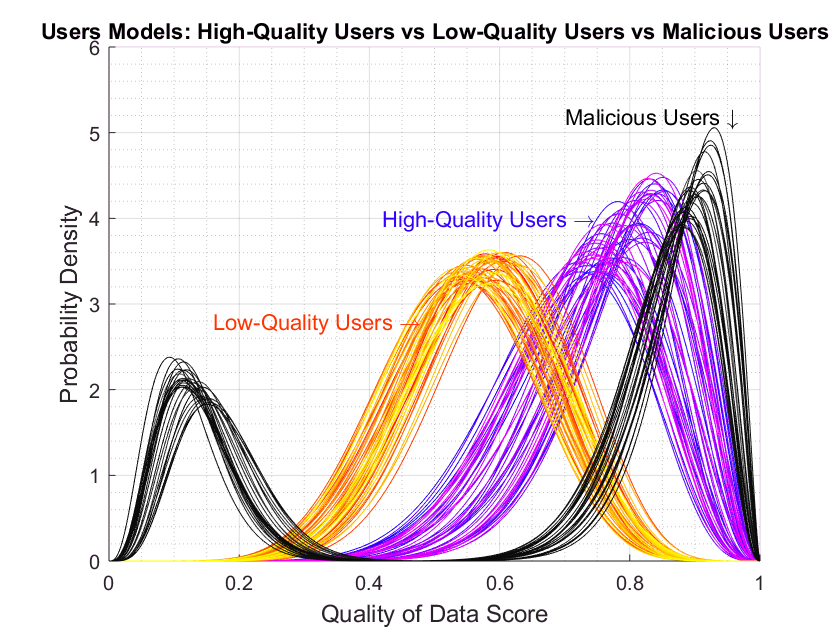

mausers1_mat = zeros(mausers_num, tasks_num);
mausers2_mat = zeros(mausers_num, tasks_num);
mausers_mat = zeros(mausers_num, tasks_num);
for i=1:mausers_num
    % High quality beta distribution model
    am1 = rand()*4 + 18; % random number in the range [18-22]
    bm1 = rand()*1 + 2.5; % random number in the range [2.5-3.5]
    amusers_pd1 = makedist('Beta', 'a', am1, 'b', bm1);
    mausers1_mat(i,:) = random(amusers_pd1, 1, tasks_num);
    % Low quality beta distribution model
    am2 = rand()*2 + 4; % random number in the range [4-6]
    bm2 = rand()*10 + 25; % random number in the range [25-35]
    amusers_pd2 = makedist('Beta', 'a', am2, 'b', bm2);
    mausers2_mat(i,:) = random(amusers_pd2, 1, tasks_num);    
    
    % the PDF for the bimodal distribution of the two beta distribution with the alpha mixture coefficient
    % bimodal_betapdf = (1-alpha)*y3 + alpha*y4
    alpha = 0.7; % mixture coefficient
    for j=1:tasks_num
        r = rand();
        if (r < alpha)
            mausers_mat(i,j) = mausers1_mat(i,j);
        else
            mausers_mat(i,j) = mausers2_mat(i,j);
        end
    end
    plot(x, alpha*pdf(amusers_pd1, x) + (1-alpha)*pdf(amusers_pd2, x), 'Color', [1/(i+2), 1/(i+2), 1/(i+2)]);
end
% 
title('Users Models: High-Quality Users vs Low-Quality Users vs Malicious Users');
xlabel('Quality of Data Score','FontSize',12);
ylabel('Probability Density','FontSize',12);

text(0.16, 2.8, 'Low-Quality Users \rightarrow','FontSize',11, 'Color', [1, 10/lqusers_num, 0]);
text(0.42, 4, 'High-Quality Users \rightarrow','FontSize',11, 'Color', [10/hqusers_num, 0, 1]);
text(0.7, 5.2, 'Malicious Users \downarrow','FontSize',11);

grid on;
grid minor;

% Combine the two beta distribution models for getting the bimodal distribution